a = smooth(meanNormTraceFreqAllAdj(3,:),9, 'moving');
b = smooth(meanNormTraceFreqAllAdj(4,:),9, 'moving');
a_diff = diff(a);
b_diff = diff(b);
b_diff2 = diff(diff(b));


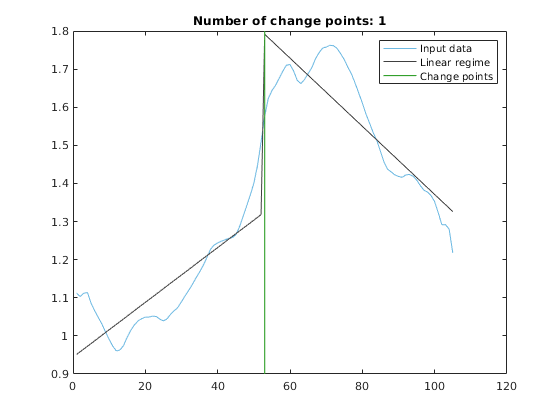

% Find change points
[changeIndices,segmentSlope,segmentIntercept] = ischange(b,'linear',...
    'Threshold',0.5);

% Display results
clf
plot(b,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot segments between change points
plot(segmentSlope(:).*(1:numel(b))'+segmentIntercept(:),'Color',[64 64 64]/255,...
    'DisplayName','Linear regime')

% Plot change points
x = repelem(find(changeIndices),3);
y2 = repmat([ylim(gca) NaN]',nnz(changeIndices),1);
plot(x,y2,'Color',[51 160 44]/255,'LineWidth',1,'DisplayName','Change points')
title(['Number of change points: ' num2str(nnz(changeIndices))])

hold off
legend

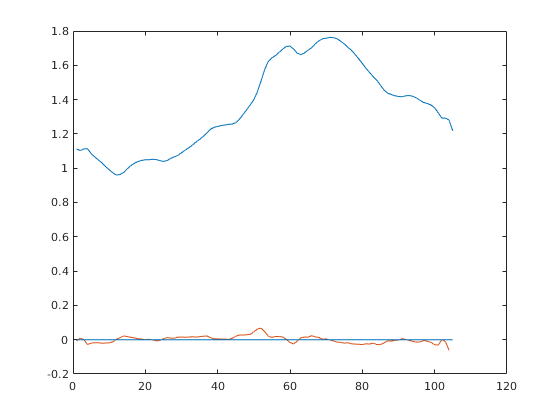

clear segmentSlope segmentIntercept x y2
figure;
% plot(a); hold on
% plot(a_diff); 
plot(b); hold on
plot(b_diff); 
line([1 105], [0 0]);


% plot(b_diff2); 
